%% ============================================================
% RIS ARRAY VALIDATION - HFSS CALIBRATED MODEL
%
% Purpose:
%   1. Evaluate RIS arrays from 2x2 to 8x8
%   2. Perform detailed hardware screening for 2x2 to 5x5
%   3. Use ACTUAL HFSS unit-cell phase and magnitude
%   4. Evaluate steering error, desired beam strength,
%      global maximum, SLL, HPBW and physical size
%
% Frequency:
%   2.45 GHz
%
% Unit cell:
%   40 mm x 40 mm
%
% Element center-to-center pitch:
%   61 mm ~= 0.5 lambda
%
% Steering:
%   X-Z plane, Phi = 0 degrees
%
% ============================================================

clear;
clc;
close all;

%% ============================================================
% 1. BASIC PARAMETERS
% ============================================================

f = 2.45e9;
c = 299792458;

lambda = c/f;
k = 2*pi/lambda;

fprintf('\n============================================\n');

fprintf('RIS ARRAY VALIDATION\n');

RIS ARRAY VALIDATION


fprintf('============================================\n');


fprintf('Frequency       = %.3f GHz\n',f/1e9);

Frequency       = 2.450 GHz


fprintf('Wavelength      = %.3f mm\n',lambda*1000);

Wavelength      = 122.364 mm



%% ============================================================
% 2. ACTUAL UNIT-CELL GEOMETRY
% ============================================================

cellSize_mm = 40;      % Physical unit-cell size
pitch_mm    = 61;      % Center-to-center spacing

cellSize = cellSize_mm*1e-3;
d        = pitch_mm*1e-3;

fprintf('\nUNIT CELL GEOMETRY\n');


UNIT CELL GEOMETRY


fprintf('Cell size       = %.1f mm\n',cellSize_mm);

Cell size       = 40.0 mm


fprintf('Element pitch   = %.1f mm\n',pitch_mm);

Element pitch   = 61.0 mm


fprintf('d/lambda        = %.3f\n',d/lambda);

d/lambda        = 0.499



%% ============================================================
% 3. ACTUAL HFSS UNIT-CELL RESPONSE
% ============================================================

% HFSS S11 magnitude in dB @ 2.45 GHz

S11_ON_dB  = -1.4661;
S11_OFF_dB = -1.3114;

% HFSS phase @ 2.45 GHz

phase_ON_deg  = 148.9220;
phase_OFF_deg = -70.2555;

% Convert S11 magnitude from dB to linear reflection coefficient

mag_ON  = 10^(S11_ON_dB/20);
mag_OFF = 10^(S11_OFF_dB/20);

% Complex reflection coefficients

Gamma_ON = mag_ON * exp(1j*deg2rad(phase_ON_deg));
Gamma_OFF = mag_OFF * exp(1j*deg2rad(phase_OFF_deg));

% Actual phase difference

deltaPhase = angle(Gamma_ON/Gamma_OFF);

deltaPhase_deg = rad2deg(deltaPhase);

fprintf('\nHFSS UNIT-CELL RESPONSE\n');


HFSS UNIT-CELL RESPONSE


fprintf('ON  |S11| = %.4f\n',mag_ON);

ON  |S11| = 0.8447


fprintf('OFF |S11| = %.4f\n',mag_OFF);

OFF |S11| = 0.8599



fprintf('ON phase   = %+8.3f deg\n',phase_ON_deg);

ON phase   = +148.922 deg


fprintf('OFF phase  = %+8.3f deg\n',phase_OFF_deg);

OFF phase  =  -70.255 deg



fprintf('Phase difference = %+8.3f deg\n',deltaPhase_deg);

Phase difference = -140.823 deg



%% ============================================================
% 4. OPTIONAL IDEAL 180 DEGREE REFERENCE
% ============================================================

% This is NOT used for the main result.
%
% It is only included so that we can see how much performance
% is lost because the practical unit cell provides ~141 deg
% instead of an ideal 180 deg phase difference.

useActualHFSS = true;

if useActualHFSS

    Gamma1 = Gamma_ON;
    Gamma0 = Gamma_OFF;

else

    % Idealized 1-bit phase states
    Gamma1 = 1;
    Gamma0 = exp(1j*pi);

end

%% ============================================================
% 5. ARRAY SIZES
% ============================================================

arraySizes = 2:8;

% Hardware candidates that can potentially fit
hardwareSizes = 2:5;

%% ============================================================
% 6. STEERING ANGLES
% ============================================================

steeringAngles = 0:5:30;

% Additional high-angle validation
highAngles = [40 50 60];

% Complete angle list

allAngles = [steeringAngles highAngles];

%% ============================================================
% 7. OBSERVATION ANGLE
% ============================================================

theta = -90:0.05:90;
thetaRad = deg2rad(theta);

%% ============================================================
% 8. RESULT STORAGE
% ============================================================

numArrays = length(arraySizes);
numAngles = length(allAngles);

peakAngle       = zeros(numArrays,numAngles);
steeringError   = zeros(numArrays,numAngles);
desiredLevel    = zeros(numArrays,numAngles);
SLL             = zeros(numArrays,numAngles);
HPBW            = zeros(numArrays,numAngles);
globalPeak      = zeros(numArrays,numAngles);

%% ============================================================
% 9. MAIN ARRAY SIMULATION
% ============================================================

for a = 1:numArrays

    N = arraySizes(a);

    % ---------------------------------------------------------
    % Element coordinates
    % ---------------------------------------------------------

    x = ((0:N-1) - (N-1)/2)*d;

    y = ((0:N-1) - (N-1)/2)*d;

    % ---------------------------------------------------------
    % Physical array dimensions
    %
    % N cells:
    %
    % Total size = (N-1)*pitch + cell size
    % ---------------------------------------------------------

    physicalSize = (N-1)*pitch_mm + cellSize_mm;

    fprintf('\n============================================\n');
    fprintf('%dx%d ARRAY\n',N,N);
    fprintf('Physical size = %.1f mm x %.1f mm\n', ...
        physicalSize,physicalSize);
    fprintf('============================================\n');

    % ---------------------------------------------------------
    % Loop over steering angles
    % ---------------------------------------------------------

    for s = 1:numAngles

        targetAngle = allAngles(s);
        targetRad = deg2rad(targetAngle);

        %% ----------------------------------------------------
        % Desired phase profile
        %
        % For Phi = 0:
        %
        % phase = -k*x*sin(theta)
        %
        %% ----------------------------------------------------

        desiredPhase = -k*x*sin(targetRad);

        %% ----------------------------------------------------
        % 1-BIT PHASE QUANTIZATION
        %
        % Choose ON/OFF state having the smaller wrapped phase
        % error.
        %% ----------------------------------------------------

        state = zeros(1,N);

        for m = 1:N

            phi = desiredPhase(m);

            errorON = angle( ...
                exp(1j*(phi-angle(Gamma1))));

            errorOFF = angle( ...
                exp(1j*(phi-angle(Gamma0))));

            if abs(errorON) <= abs(errorOFF)
                state(m) = 1;
            else
                state(m) = 0;
            end

        end

        %% ----------------------------------------------------
        % Array factor
        %
        % Because Phi = 0, Y coordinate does not contribute
        % to the phase progression.
        %
        % However, each X state is replicated across Y.
        %% ----------------------------------------------------

        AF = zeros(size(theta));

        for m = 1:N

            if state(m) == 1
                Gamma = Gamma1;
            else
                Gamma = Gamma0;
            end

            % Each X column contains N identical elements

            for n = 1:N

                xm = x(m);

                spatialPhase = ...
                    k*xm*sin(thetaRad);

                AF = AF + ...
                    Gamma .* exp(1j*spatialPhase);

            end

        end

        %% ----------------------------------------------------
        % Normalize
        %% ----------------------------------------------------

        AFmag = abs(AF);

        AFmag = AFmag ./ max(AFmag);

        AFdB = 20*log10(AFmag + eps);

        %% ----------------------------------------------------
        % GLOBAL MAXIMUM
        %% ----------------------------------------------------

        [globalValue,indexGlobal] = max(AFdB);

        globalAngle = theta(indexGlobal);

        globalPeak(a,s) = globalValue;
        peakAngle(a,s) = globalAngle;

        %% ----------------------------------------------------
        % DESIRED DIRECTION RESPONSE
        %% ----------------------------------------------------

        [~,targetIndex] = ...
            min(abs(theta-targetAngle));

        desiredValue = AFdB(targetIndex);

        desiredLevel(a,s) = desiredValue;

        %% ----------------------------------------------------
        % STEERING ERROR
        %% ----------------------------------------------------

        steeringError(a,s) = ...
            globalAngle-targetAngle;

        %% ----------------------------------------------------
        % HPBW
        %% ----------------------------------------------------

        HPBW(a,s) = calculateHPBW(theta,AFdB,indexGlobal);

        %% ----------------------------------------------------
        % SIDELOBE LEVEL
        %% ----------------------------------------------------

        SLL(a,s) = calculateSLL(theta,AFdB,indexGlobal);

    end

end

2x2 ARRAY


Physical size = 101.0 mm x 101.0 mm


3x3 ARRAY


Physical size = 162.0 mm x 162.0 mm


4x4 ARRAY


Physical size = 223.0 mm x 223.0 mm


5x5 ARRAY


Physical size = 284.0 mm x 284.0 mm


6x6 ARRAY


Physical size = 345.0 mm x 345.0 mm


7x7 ARRAY


Physical size = 406.0 mm x 406.0 mm


8x8 ARRAY


Physical size = 467.0 mm x 467.0 mm



%% ============================================================
% 10. PRINT FULL RESULTS
% ============================================================

fprintf('\n\n');
fprintf('============================================================\n');

fprintf('FULL ARRAY VALIDATION RESULTS\n');

FULL ARRAY VALIDATION RESULTS


fprintf('============================================================\n');


for a = 1:numArrays

    N = arraySizes(a);

    physicalSize = (N-1)*pitch_mm + cellSize_mm;

    fprintf('\n--------------------------------------------\n');
    fprintf('%dx%d RIS | Physical size = %.1f mm\n', ...
        N,N,physicalSize);
    fprintf('--------------------------------------------\n');

    fprintf(['Target   Global   Error   Desired   SLL   HPBW\n']);

    for s = 1:numAngles

        fprintf('%+5.1f   %+7.2f   %+6.2f   %+7.2f   %+6.2f   %6.2f\n', ...
            allAngles(s), ...
            peakAngle(a,s), ...
            steeringError(a,s), ...
            desiredLevel(a,s), ...
            SLL(a,s), ...
            HPBW(a,s));

    end

end


--------------------------------------------


2x2 RIS | Physical size = 101.0 mm


--------------------------------------------


Target   Global   Error   Desired   SLL   HPBW


 +0.0     +0.00    +0.00     +0.00    -0.00    60.10
 +5.0     +0.00    -5.00     -0.08    -0.00    60.10
+10.0     +0.00   -10.00     -0.33    -0.00    60.10
+15.0     +0.00   -15.00     -0.73    -0.00    60.10
+20.0     +0.00   -20.00     -1.31    -0.00    60.10
+25.0     +0.00   -25.00     -2.06    -0.00    60.10
+30.0    -51.70   -81.70     -7.39    -0.00      NaN
+40.0    -51.70   -91.70     -4.20    -0.00      NaN
+50.0    -51.70   -101.70     -2.42    -0.00      NaN
+60.0    -51.70   -111.70     -1.42    -0.00      NaN



--------------------------------------------


3x3 RIS | Physical size = 162.0 mm


--------------------------------------------


Target   Global   Error   Desired   SLL   HPBW


 +0.0     +0.00    +0.00     +0.00    -9.54    36.30
 +5.0     +0.00    -5.00     -0.22    -9.54    36.30
+10.0     +0.00   -10.00     -0.88    -9.54    36.30
+15.0    -23.05   -38.05     -7.06    -2.40    38.70
+20.0    -23.05   -43.05     -5.21    -2.40    38.70
+25.0    -23.05   -48.05     -3.76    -2.40    38.70
+30.0    -23.05   -53.05     -2.86    -2.40    38.70
+40.0    -23.05   -63.05     -2.45    -2.40    38.70
+50.0    -23.05   -73.05     -3.37    -2.40    38.70
+60.0    -90.00   -150.00     -0.55    +0.00      NaN



--------------------------------------------


4x4 RIS | Physical size = 223.0 mm


--------------------------------------------


Target   Global   Error   Desired   SLL   HPBW


 +0.0     +0.00    +0.00     +0.00   -11.30    26.40
 +5.0     +0.00    -5.00     -0.41   -11.30    26.40
+10.0    -13.60   -23.60     -4.58    -3.45    28.45
+15.0    -13.60   -28.60     -4.06    -3.45    28.45
+20.0    -13.60   -33.60     -3.52    -3.45    28.45
+25.0    -13.60   -38.60     -3.58    -3.45    28.45
+30.0    -18.05   -48.05     -2.16    -2.11    26.50
+40.0    +45.40    +5.40     -0.30    -0.00    47.15
+50.0    +45.40    -4.60     -0.17    -0.00    47.15
+60.0    +73.45   +13.45     -0.49    -0.00      NaN



--------------------------------------------


5x5 RIS | Physical size = 284.0 mm


--------------------------------------------


Target   Global   Error   Desired   SLL   HPBW


 +0.0     +0.00    +0.00     +0.00   -12.04    20.90
 +5.0     +0.00    -5.00     -0.66   -12.04    20.90
+10.0     -8.65   -18.65     -3.43    -5.43    25.95
+15.0    -13.55   -28.55     -3.85    -2.51    20.40
+20.0    -13.55   -33.55     -2.55    -2.51    20.40
+25.0    +31.10    +6.10     -0.93    -0.95    22.55
+30.0    +31.10    +1.10     -0.03    -0.95    22.55
+40.0    +42.90    +2.90     -0.16    -1.24    25.60
+50.0    +42.90    -7.10     -0.83    -1.24    25.60
+60.0    -58.30   -118.30     -0.46    -0.00      NaN



--------------------------------------------


6x6 RIS | Physical size = 345.0 mm


--------------------------------------------


Target   Global   Error   Desired   SLL   HPBW


 +0.0     +0.00    +0.00     +0.00   -12.43    17.30
 +5.0     +0.00    -5.00     -0.97   -12.43    17.30
+10.0    -10.35   -20.35     -5.05    -2.98    16.95
+15.0    -10.35   -25.35     -3.08    -2.98    16.95
+20.0    +23.20    +3.20     -0.41    -0.50    16.75
+25.0    +23.20    -1.80     -0.13    -0.50    16.75
+30.0    +32.45    +2.45     -0.20    -1.62    18.45
+40.0    +36.85    -3.15     -0.26    -0.00    20.60
+50.0    -51.10   -101.10     -0.59    -0.00    26.35
+60.0    -62.40   -122.40     -1.40    -0.00      NaN



--------------------------------------------


7x7 RIS | Physical size = 406.0 mm


--------------------------------------------


Target   Global   Error   Desired   SLL   HPBW


 +0.0     +0.00    +0.00     +0.00   -12.65    14.70
 +5.0     -3.80    -8.80     -1.97    -7.29    19.60
+10.0     -8.10   -18.10     -3.93    -3.38    14.90
+15.0     -9.60   -24.60     -2.54    -2.54    14.15
+20.0    +20.05    +0.05     -0.00    -0.66    14.30
+25.0    +29.05    +4.05     -0.80    -0.97    16.10
+30.0    +29.05    -0.95     -0.04    -0.97    16.10
+40.0    -43.45   -83.45     -1.23    -1.08    19.90
+50.0    -51.15   -101.15     -1.14    -0.86    21.25
+60.0    -53.65   -113.65     -0.65    -0.47    25.95



--------------------------------------------


8x8 RIS | Physical size = 467.0 mm


--------------------------------------------


Target   Global   Error   Desired   SLL   HPBW


 +0.0     +0.00    +0.00     +0.00   -12.80    12.90
 +5.0     -2.60    -7.60     -2.06    -8.01    16.65
+10.0     -8.05   -18.05     -3.44    -2.79    12.40
+15.0    +16.50    +1.50     -0.18    -0.18    12.00
+20.0    +19.00    -1.00     -0.07    -0.63    12.55
+25.0    +23.50    -1.50     -0.15    -1.33    13.05
+30.0    +26.95    -3.05     -0.53    -0.55    13.75
+40.0    -42.30   -82.30     -1.49    -0.89    16.05
+50.0    -46.55   -96.55     -0.20    -0.00    19.45
+60.0    +59.50    -0.50     -0.00    -0.00      NaN



%% ============================================================
% 11. HARDWARE SCREENING
% ============================================================

fprintf('\n\n');
fprintf('============================================================\n');

fprintf('HARDWARE SCREENING\n');

HARDWARE SCREENING


fprintf('============================================================\n');


fprintf('\n');
fprintf('Array   Size(mm)   Elements   PIN Diodes   Control Lines\n');

Array   Size(mm)   Elements   PIN Diodes   Control Lines



for a = 1:length(hardwareSizes)

    N = hardwareSizes(a);

    physicalSize = (N-1)*pitch_mm + cellSize_mm;

    elements = N^2;

    fprintf('%2dx%-2d    %7.1f      %3d        %3d          %3d\n', ...
        N,N,physicalSize,elements,elements,elements);

end

 2x2       101.0        4          4            4
 3x3       162.0        9          9            9
 4x4       223.0       16         16           16
 5x5       284.0       25         25           25



%% ============================================================
% 12. HARDWARE DECISION TABLE
% ============================================================

fprintf('\n');
fprintf('============================================================\n');

fprintf('HARDWARE FEASIBILITY\n');

HARDWARE FEASIBILITY


fprintf('============================================================\n');


maxBoardSize_mm = 240;

fprintf('\nMaximum assumed board dimension = %.1f mm\n', ...
    maxBoardSize_mm);


Maximum assumed board dimension = 240.0 mm



fprintf('\n');
fprintf('Array   Physical(mm)   Fits?   Margin(mm)\n');

Array   Physical(mm)   Fits?   Margin(mm)



for a = 1:numArrays

    N = arraySizes(a);

    physicalSize = (N-1)*pitch_mm + cellSize_mm;

    margin = maxBoardSize_mm - physicalSize;

    if physicalSize <= maxBoardSize_mm
        fitsText = 'YES';
    else
        fitsText = 'NO';
    end

    fprintf('%2dx%-2d    %8.1f      %-5s     %+7.1f\n', ...
        N,N,physicalSize,fitsText,margin);

end

 2x2        101.0      YES        +139.0
 3x3        162.0      YES         +78.0
 4x4        223.0      YES         +17.0
 5x5        284.0      NO          -44.0
 6x6        345.0      NO         -105.0
 7x7        406.0      NO         -166.0
 8x8        467.0      NO         -227.0



%% ============================================================
% 13. MEAN AND MAXIMUM STEERING ERROR
% ============================================================

meanError = zeros(numArrays,1);
maxError = zeros(numArrays,1);
meanDesired = zeros(numArrays,1);
meanSLL = zeros(numArrays,1);
meanHPBW = zeros(numArrays,1);

for a = 1:numArrays

    meanError(a) = mean(abs(steeringError(a,:)));

    maxError(a) = max(abs(steeringError(a,:)));

    meanDesired(a) = mean(desiredLevel(a,:));

    meanSLL(a) = mean(SLL(a,:));

    meanHPBW(a) = mean(HPBW(a,:));

end

%% ============================================================
% 14. SUMMARY TABLE
% ============================================================

fprintf('\n\n');
fprintf('============================================================\n');

fprintf('ARRAY SUMMARY\n');

ARRAY SUMMARY


fprintf('============================================================\n');


fprintf('\n');
fprintf('Array   Size(mm)   Elements   MeanErr   MaxErr   MeanDesired   MeanSLL   MeanHPBW\n');

Array   Size(mm)   Elements   MeanErr   MaxErr   MeanDesired   MeanSLL   MeanHPBW


fprintf('-----------------------------------------------------------------------------------\n');

-----------------------------------------------------------------------------------



for a = 1:numArrays

    N = arraySizes(a);

    physicalSize = (N-1)*pitch_mm + cellSize_mm;

    fprintf('%2dx%-2d   %7.1f      %3d      %7.2f   %7.2f      %8.2f    %7.2f    %8.2f\n', ...
        N, ...
        N, ...
        physicalSize, ...
        N^2, ...
        meanError(a), ...
        maxError(a), ...
        meanDesired(a), ...
        meanSLL(a), ...
        meanHPBW(a));

end

 2x2      101.0        4        46.18    111.70         -1.99      -0.00         NaN
 3x3      162.0        9        48.33    150.00         -2.64      -4.30         NaN
 4x4      223.0       16        20.09     48.05         -1.93      -3.85         NaN
 5x5      284.0       25        22.12    118.30         -1.29      -3.89         NaN
 6x6      345.0       36        28.48    122.40         -1.21      -3.34         NaN
 7x7      406.0       49        35.48    113.65         -1.23      -3.09       17.69
 8x8      467.0       64        21.21     96.55         -0.81      -2.72         NaN


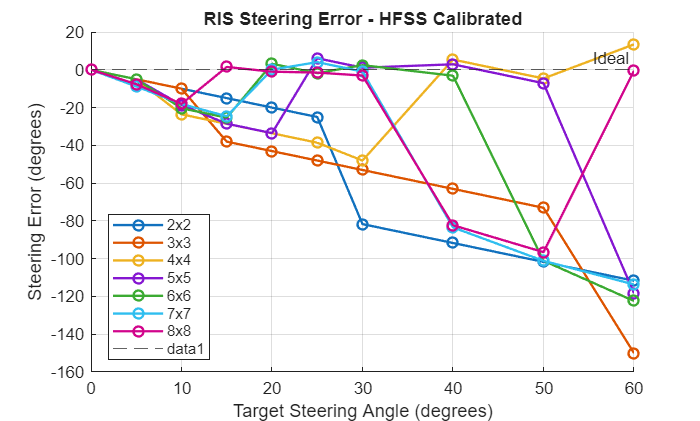

%% ============================================================
% 15. FULL STEERING ERROR PLOT
% ============================================================

figure;

hold on;

for a = 1:numArrays

    plot(allAngles, ...
        steeringError(a,:), ...
        '-o', ...
        'LineWidth',1.4, ...
        'DisplayName',sprintf('%dx%d', ...
        arraySizes(a),arraySizes(a)));

end

yline(0,'--','Ideal');

grid on;

xlabel('Target Steering Angle (degrees)');
ylabel('Steering Error (degrees)');

title('RIS Steering Error - HFSS Calibrated');

legend('Location','best');

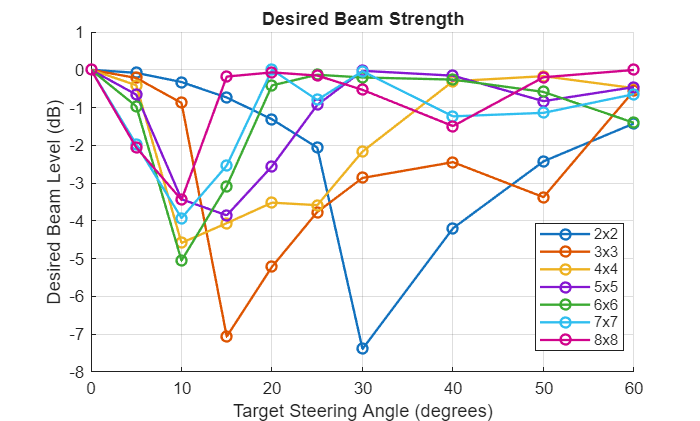


%% ============================================================
% 16. DESIRED BEAM STRENGTH
% ============================================================

figure;

hold on;

for a = 1:numArrays

    plot(allAngles, ...
        desiredLevel(a,:), ...
        '-o', ...
        'LineWidth',1.4, ...
        'DisplayName',sprintf('%dx%d', ...
        arraySizes(a),arraySizes(a)));

end

grid on;

xlabel('Target Steering Angle (degrees)');
ylabel('Desired Beam Level (dB)');

title('Desired Beam Strength');

legend('Location','best');

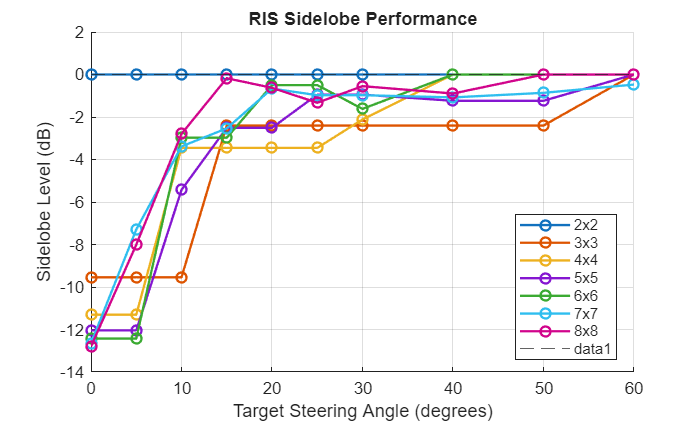


%% ============================================================
% 17. SIDELobe LEVEL
% ============================================================

figure;

hold on;

for a = 1:numArrays

    plot(allAngles, ...
        SLL(a,:), ...
        '-o', ...
        'LineWidth',1.4, ...
        'DisplayName',sprintf('%dx%d', ...
        arraySizes(a),arraySizes(a)));

end

yline(0,'--');

grid on;

xlabel('Target Steering Angle (degrees)');
ylabel('Sidelobe Level (dB)');

title('RIS Sidelobe Performance');

legend('Location','best');

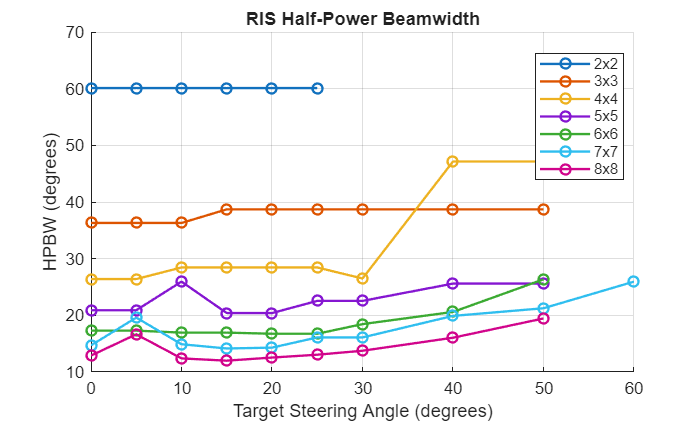


%% ============================================================
% 18. HPBW
% ============================================================

figure;

hold on;

for a = 1:numArrays

    plot(allAngles, ...
        HPBW(a,:), ...
        '-o', ...
        'LineWidth',1.4, ...
        'DisplayName',sprintf('%dx%d', ...
        arraySizes(a),arraySizes(a)));

end

grid on;

xlabel('Target Steering Angle (degrees)');
ylabel('HPBW (degrees)');

title('RIS Half-Power Beamwidth');

legend('Location','best');

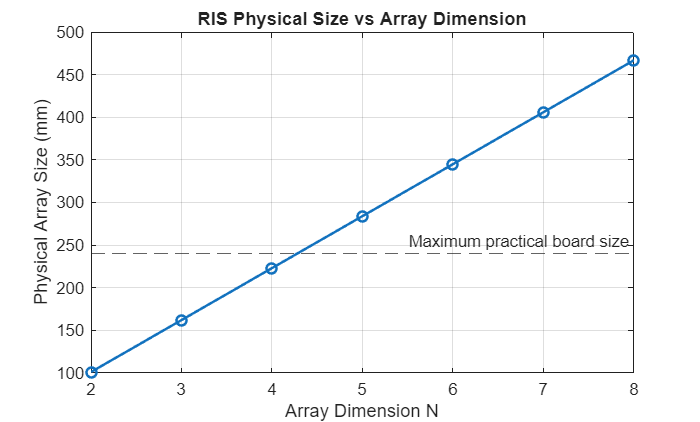


%% ============================================================
% 19. PHYSICAL SIZE
% ============================================================

physicalSizes = zeros(size(arraySizes));

for a = 1:numArrays

    N = arraySizes(a);

    physicalSizes(a) = ...
        (N-1)*pitch_mm + cellSize_mm;

end

figure;

plot(arraySizes, ...
    physicalSizes, ...
    '-o', ...
    'LineWidth',1.5);

hold on;

yline(maxBoardSize_mm,'--', ...
    'Maximum practical board size');

grid on;

xlabel('Array Dimension N');
ylabel('Physical Array Size (mm)');

title('RIS Physical Size vs Array Dimension');

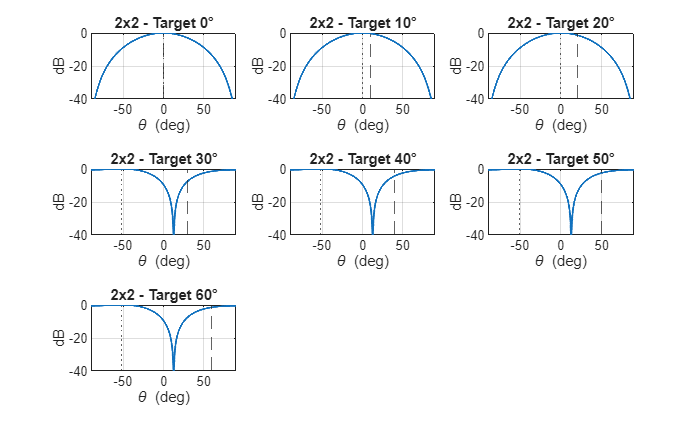

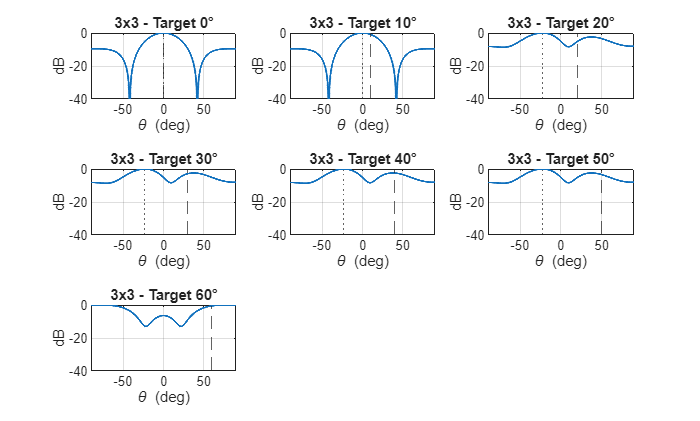

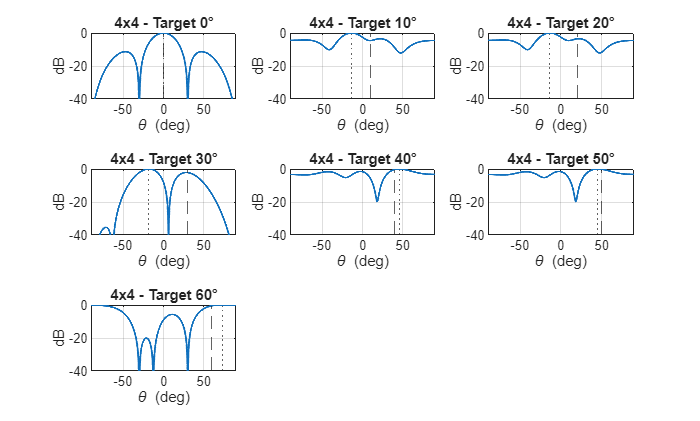

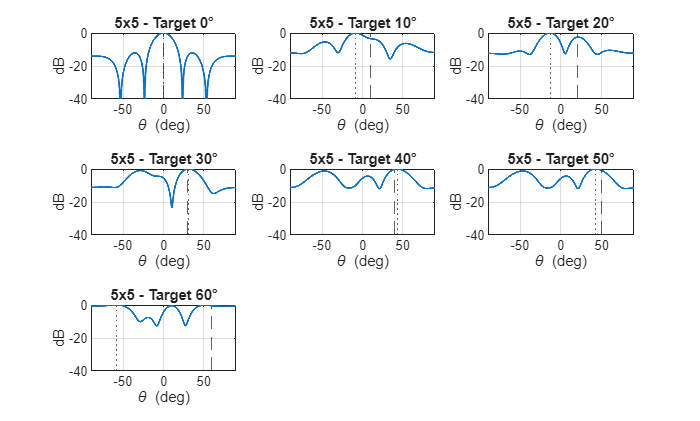

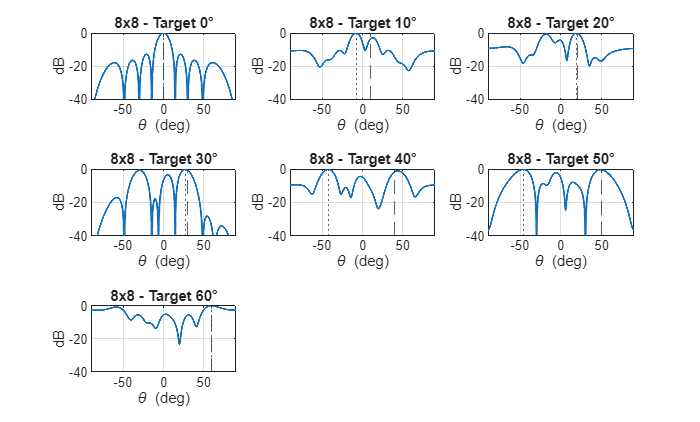


%% ============================================================
% 20. DETAILED PATTERN PLOTS
%
% Only the hardware candidates and 8x8 benchmark are shown.
% This avoids producing dozens of figures.
% ============================================================

selectedArrays = [2 3 4 5 8];

selectedAngles = [0 10 20 30 40 50 60];

for N = selectedArrays

    a = find(arraySizes == N);

    figure;

    tiledlayout(3,3);

    for q = 1:length(selectedAngles)

        targetAngle = selectedAngles(q);

        targetRad = deg2rad(targetAngle);

        x = ((0:N-1) - (N-1)/2)*d;

        desiredPhase = ...
            -k*x*sin(targetRad);

        state = zeros(1,N);

        for m = 1:N

            phi = desiredPhase(m);

            errorON = angle( ...
                exp(1j*(phi-angle(Gamma1))));

            errorOFF = angle( ...
                exp(1j*(phi-angle(Gamma0))));

            if abs(errorON) <= abs(errorOFF)
                state(m) = 1;
            else
                state(m) = 0;
            end

        end

        AF = zeros(size(theta));

        for m = 1:N

            if state(m) == 1
                Gamma = Gamma1;
            else
                Gamma = Gamma0;
            end

            for n = 1:N

                xm = x(m);

                AF = AF + ...
                    Gamma .* exp( ...
                    1j*k*xm*sin(thetaRad));

            end

        end

        AFmag = abs(AF);

        AFmag = AFmag/max(AFmag);

        AFdB = 20*log10(AFmag+eps);

        nexttile;

        plot(theta,AFdB,'LineWidth',1.2);

        hold on;

        xline(targetAngle,'--');

        xline(peakAngle(a,...
            find(allAngles==targetAngle)),':');

        grid on;

        xlabel('\theta (deg)');
        ylabel('dB');

        title(sprintf('%dx%d - Target %d°', ...
            N,N,targetAngle));

        ylim([-40 0]);
        xlim([-90 90]);

    end

end

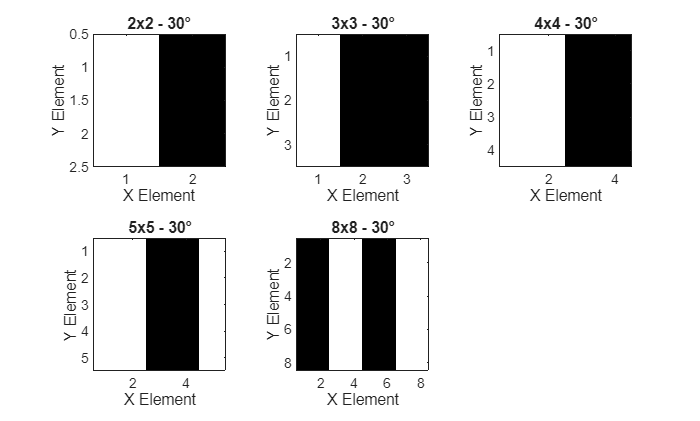


%% ============================================================
% 21. BINARY CONFIGURATION
% ============================================================

targetAngle = 30;

figure;

for q = 1:length(selectedArrays)

    N = selectedArrays(q);

    x = ((0:N-1) - (N-1)/2)*d;

    desiredPhase = ...
        -k*x*sin(deg2rad(targetAngle));

    state = zeros(1,N);

    for m = 1:N

        phi = desiredPhase(m);

        errorON = angle( ...
            exp(1j*(phi-angle(Gamma1))));

        errorOFF = angle( ...
            exp(1j*(phi-angle(Gamma0))));

        if abs(errorON) <= abs(errorOFF)
            state(m) = 1;
        else
            state(m) = 0;
        end

    end

    nexttile;

    imagesc(repmat(state,N,1));

    colormap(gray);

    axis equal tight;

    xlabel('X Element');
    ylabel('Y Element');

    title(sprintf('%dx%d - 30°',N,N));

end


%% ============================================================
% 22. HARDWARE CANDIDATE RANKING
% ============================================================

fprintf('\n\n');
fprintf('============================================================\n');

fprintf('HARDWARE CANDIDATE RANKING\n');

HARDWARE CANDIDATE RANKING


fprintf('============================================================\n');


fprintf('\n');

fprintf(['This ranking is only a screening aid.\n' ...
         'Final selection should consider HFSS full-array validation.\n\n']);

This ranking is only a screening aid.
Final selection should consider HFSS full-array validation.




for a = 1:length(hardwareSizes)

    N = hardwareSizes(a);

    idx = find(arraySizes == N);

    physicalSize = physicalSizes(idx);

    fprintf('%dx%d:\n',N,N);

    fprintf('  Physical size      : %.1f mm\n', ...
        physicalSize);

    fprintf('  Elements           : %d\n',N^2);

    fprintf('  Mean steering error: %.2f deg\n', ...
        meanError(idx));

    fprintf('  Maximum error      : %.2f deg\n', ...
        maxError(idx));

    fprintf('  Mean desired level : %.2f dB\n', ...
        meanDesired(idx));

    fprintf('  Mean SLL           : %.2f dB\n', ...
        meanSLL(idx));

    fprintf('  Mean HPBW          : %.2f deg\n', ...
        meanHPBW(idx));

    if physicalSize <= maxBoardSize_mm
        fprintf('  Hardware           : FEASIBLE\n');
    else
        fprintf('  Hardware           : TOO LARGE\n');
    end

    fprintf('\n');

end

2x2:


  Physical size      : 101.0 mm


  Elements           : 4


  Mean steering error: 46.18 deg


  Maximum error      : 111.70 deg


  Mean desired level : -1.99 dB


  Mean SLL           : -0.00 dB


  Mean HPBW          : NaN deg


  Hardware           : FEASIBLE


3x3:


  Physical size      : 162.0 mm


  Elements           : 9


  Mean steering error: 48.33 deg


  Maximum error      : 150.00 deg


  Mean desired level : -2.64 dB


  Mean SLL           : -4.30 dB


  Mean HPBW          : NaN deg


  Hardware           : FEASIBLE


4x4:


  Physical size      : 223.0 mm


  Elements           : 16


  Mean steering error: 20.09 deg


  Maximum error      : 48.05 deg


  Mean desired level : -1.93 dB


  Mean SLL           : -3.85 dB


  Mean HPBW          : NaN deg


  Hardware           : FEASIBLE


5x5:


  Physical size      : 284.0 mm


  Elements           : 25


  Mean steering error: 22.12 deg


  Maximum error      : 118.30 deg


  Mean desired level : -1.29 dB


  Mean SLL           : -3.89 dB


  Mean HPBW          : NaN deg


  Hardware           : TOO LARGE



fprintf('\n============================================================\n');

fprintf('END OF RIS VALIDATION\n');

END OF RIS VALIDATION


fprintf('============================================================\n');



%% ============================================================
% LOCAL FUNCTION: HPBW
% ============================================================

function width = calculateHPBW(theta,AFdB,peakIndex)

    halfPower = AFdB(peakIndex)-3;

    % Search left

    leftIndex = peakIndex;

    while leftIndex > 1 && ...
            AFdB(leftIndex) > halfPower

        leftIndex = leftIndex-1;

    end

    % Search right

    rightIndex = peakIndex;

    while rightIndex < length(AFdB) && ...
            AFdB(rightIndex) > halfPower

        rightIndex = rightIndex+1;

    end

    if leftIndex == 1 || rightIndex == length(AFdB)

        width = NaN;

    else

        leftAngle = theta(leftIndex);
        rightAngle = theta(rightIndex);

        width = rightAngle-leftAngle;

    end

end


%% ============================================================
% LOCAL FUNCTION: SLL
% ============================================================

function sll = calculateSLL(theta,AFdB,peakIndex)

    % Find local minima around the main beam.

    minima = islocalmin(AFdB);

    leftMinima = find(minima(1:peakIndex));

    rightMinima = ...
        find(minima(peakIndex:end)) ...
        + peakIndex - 1;

    if ~isempty(leftMinima) && ...
            ~isempty(rightMinima)

        leftNull = leftMinima(end);
        rightNull = rightMinima(1);

        sideRegion = true(size(AFdB));

        sideRegion(leftNull:rightNull) = false;

        sideRegion(peakIndex) = false;

        sidelobeValues = AFdB(sideRegion);

        if isempty(sidelobeValues)

            sll = NaN;

        else

            sll = max(sidelobeValues);

        end

    else

        % Fallback if a clear pair of minima is unavailable

        exclusion = 5;

        sideRegion = true(size(AFdB));

        leftBound = max(1,peakIndex-exclusion);
        rightBound = min(length(AFdB),peakIndex+exclusion);

        sideRegion(leftBound:rightBound) = false;

        sidelobeValues = AFdB(sideRegion);

        if isempty(sidelobeValues)

            sll = NaN;

        else

            sll = max(sidelobeValues);

        end

    end

end